clear;

a2r=pi/180;
the=60*a2r; phi=45*a2r; psi=30*a2r;
x=[3;2;7];

Rx=[1 0 0;0 cos(the) -sin(the);0 sin(the) cos(the)] % roll

Rx =    1.000000000000000                   0                   0
                   0   0.500000000000000  -0.866025403784439
                   0   0.866025403784439   0.500000000000000


Ry=[cos(phi) 0 sin(phi);0 1 0;-sin(phi) 0 cos(phi)] % pitch

Ry =    0.707106781186548                   0   0.707106781186547
                   0   1.000000000000000                   0
  -0.707106781186547                   0   0.707106781186548


Rz=[cos(psi) -sin(psi) 0;sin(psi) cos(psi) 0;0 0 1] % yaw

Rz =    0.866025403784439  -0.500000000000000                   0
   0.500000000000000   0.866025403784439                   0
                   0                   0   1.000000000000000



Rx*x

ans =    3.000000000000000
  -5.062177826491070
   5.232050807568879


Ry*(Rx*x)

ans =    5.820938949104148
  -5.062177826491070
   1.578298261984864


Rz*(Ry*(Rx*x))

ans =    7.572169917048021
  -1.473505121663488
   1.578298261984864



y=Rz*Ry*Rx*x

y =    7.572169917048020
  -1.473505121663487
   1.578298261984864


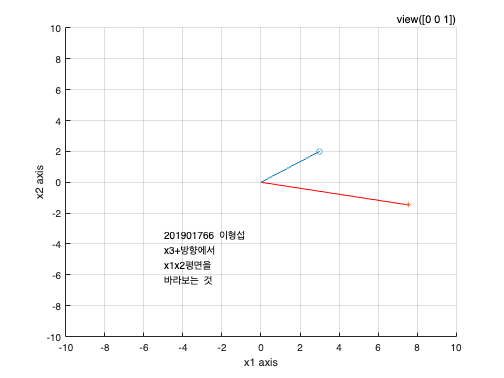


figure(1); clf;
plot3(x(1),x(2),x(3),'o'); grid; hold on;
plot3(y(1),y(2),y(3),'*');
xlabel('x1 axis'); ylabel('x2 axis'); zlabel('x3 axis');
axis([-10 10 -10 10 -10 10]);
line([0 x(1)],[0 x(2)],[0 x(3)]);
line([0 y(1)],[0 y(2)],[0 y(3)],'color','red');

str={'201901766 이형섭\newlinex3+방향에서\newlinex1x2평면을\newline바라보는 것'};
text(-5,-5,-10,str)
view([0 0 1])

title('view([0 0 1])')
ax = gca;
ax.TitleHorizontalAlignment = 'right';